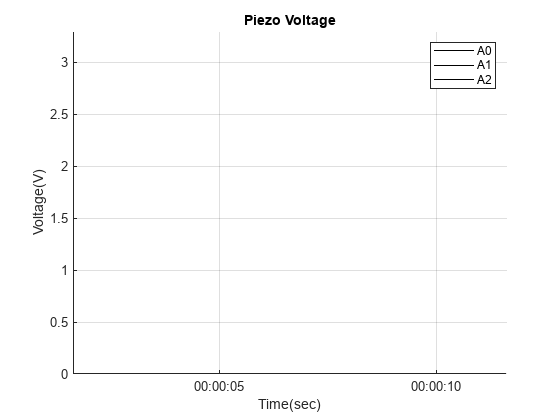

% seismic_sim.mlx
% Picks up data from Arduino pins in real time and saves, plots, 
% and processes the data as described in the thesis document
% Code referenced: https://www.ee-diary.com/2021/10/how-to-plot-real-time-data-from-arduino.html#

clear
clc
clf

%Press ctrl+C to exit"

try
% create instance of arduino object
a = arduino("COM3", "Uno",'BaudRate',32768);
configurePin(a, "A0", "AnalogInput");
configurePin(a, "A1", "AnalogInput");
configurePin(a, "A2", "AnalogInput");

%set-up graph
h = animatedline;
h1 = animatedline;
h2 = animatedline;
% set axis using get current axis(gca)
ax = gca;
% set x-axis label
xlabel('Time(sec)');
% set x-axis label
ylabel('Voltage(V)');
% set title for graph
title('Piezo Voltage');
legend("A0", "A1", "A2")
% set y-axis limit from 0 to 5.2V
ax.YLim = [0 3.3];
% turn on grid
grid on;

% set start time
startTime = datetime('now');
% start timer
tic;
loop_duration = 30;

while toc < loop_duration
    % Read current voltage value
    v = readVoltage(a,'A0');
    v1 = readVoltage(a,'A1');
    v2 = readVoltage(a,'A2'); 
    % Get current time
    t =  datetime('now') - startTime;
    % Add points to animation
    addpoints(h,datenum(t),v);
    addpoints(h1,datenum(t),v1);
    addpoints(h2,datenum(t),v2);
    % Update X-axis limit
    ax.XLim = datenum([t-seconds(10) t]);
    datetick('x','keeplimits');
    drawnow limitrate;
end

catch
    %in case of error or arduino gets disconnected
    disp('Failed!');
    clear;
    close;
end